YUVtoRGB=[1 0 1.402;
    1 -0.34413 -0.71414;
    1 1.772 0];

load yuvdata.mat;

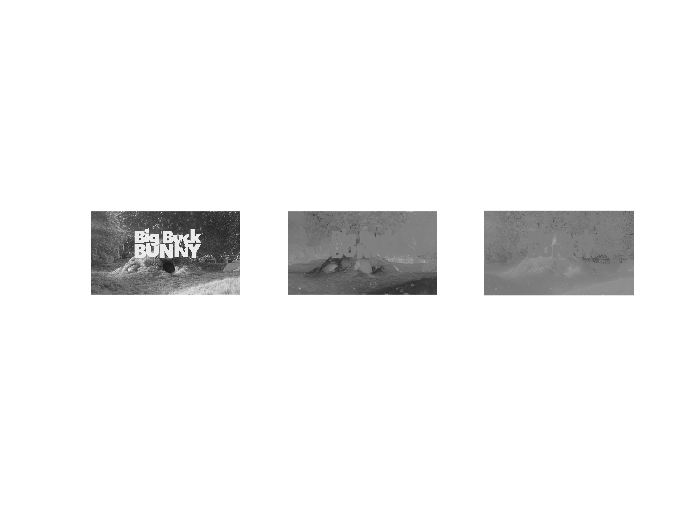

Iyy=reshape(yy,[cols rows]);
size(Iyy);
%Iyy=uint8(Iyy);


Iuu=reshape(uu,[cols/2 rows/2]);
size(Iuu);
%Iuu=double(Iuu);

Ivv=reshape(vv,[cols/2 rows/2]);
size(Ivv);
%Ivv=double(Ivv);

figure();
subplot(1,3,1); imshow(uint8(Iyy'))
subplot(1,3,2); imshow(uint8(Iuu'))
subplot(1,3,3); imshow(uint8(Ivv'))

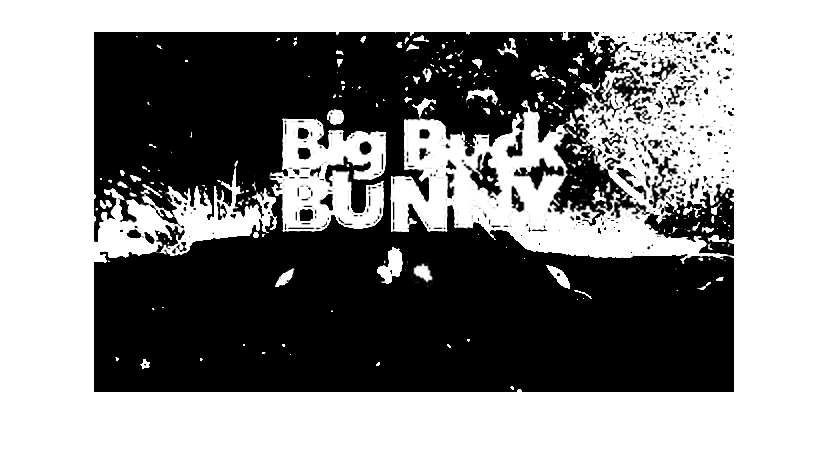


Iuu=Iuu-127;
Ivv=Ivv-127;
figure;
Iuu=imresize(Iuu, [cols rows]);
Ivv=imresize(Ivv, [cols rows]);

imshow(Iuu');

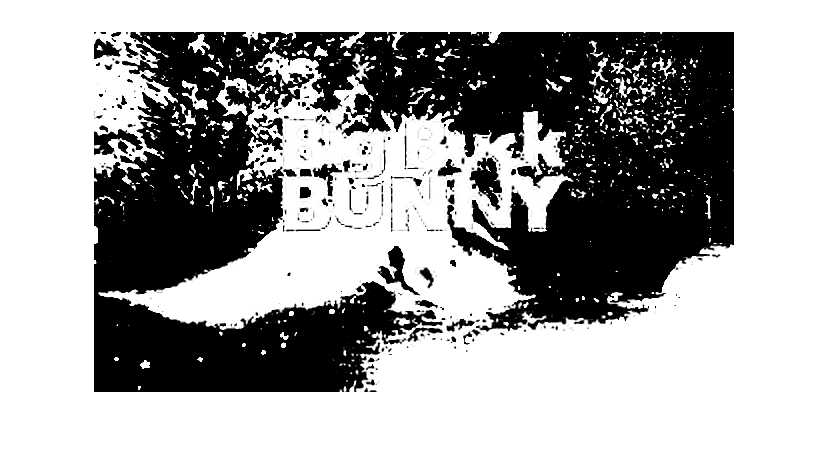


figure;
imshow(Ivv');

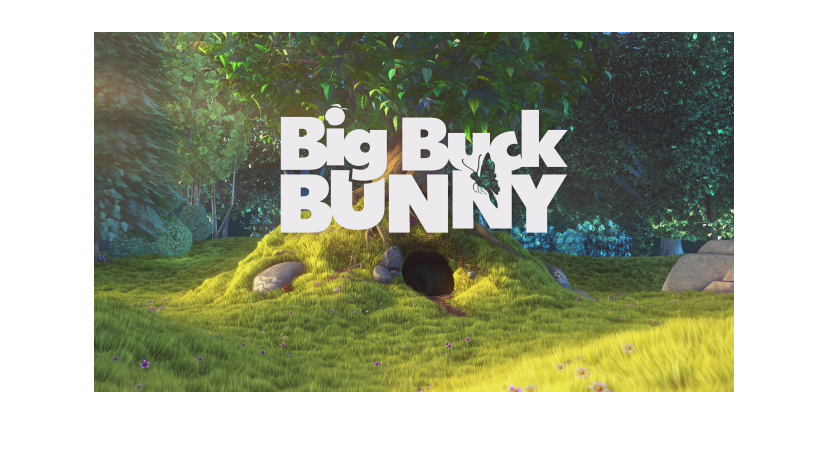


YUV=cat(2,Iyy(:),Iuu(:),Ivv(:));
size(YUV);
RGB=(YUVtoRGB*YUV')';
R=reshape(RGB(:,1),[cols rows])';
G=reshape(RGB(:,2),[cols rows])';
B=reshape(RGB(:,3),[cols rows])';

RGBfinal=cat(3,R,G,B);
figure;
imshow(uint8(RGBfinal))

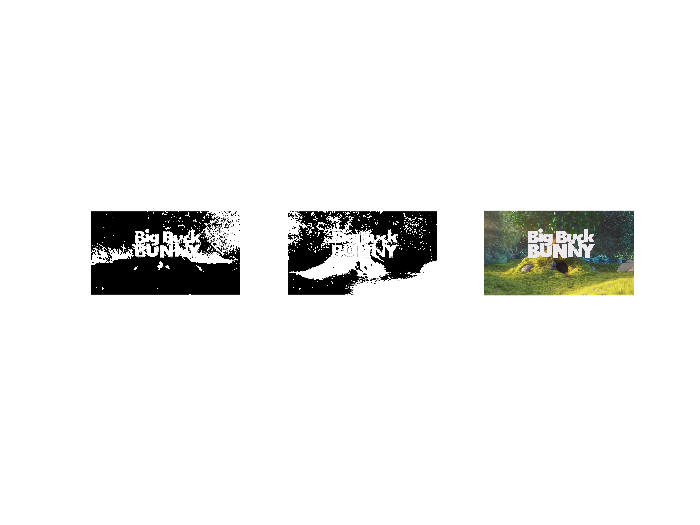


figure();
subplot(1,3,1); imshow(Iuu');
subplot(1,3,2); imshow(Ivv');
subplot(1,3,3); imshow(uint8(RGBfinal))

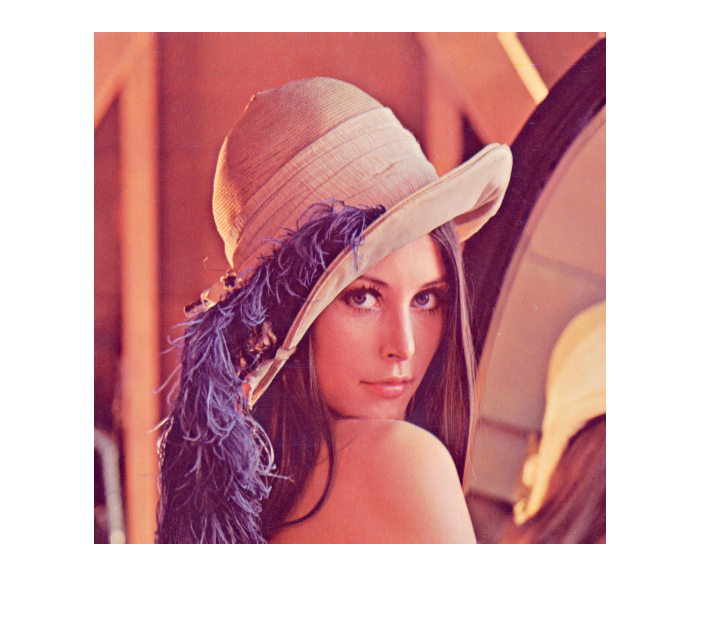

I=imread("lena.tiff");
figure;
imshow(I)

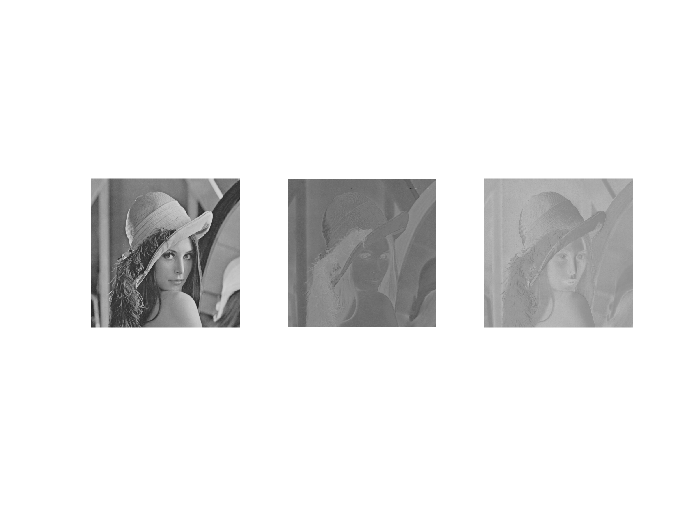


Iycbcr=rgb2ycbcr(I);

y=Iycbcr(:,:,1);
cb=Iycbcr(:,:,2);
cr=Iycbcr(:,:,3);

figure();
subplot(1,3,1); imshow(uint8(y))
subplot(1,3,2); imshow(uint8(cb))
subplot(1,3,3); imshow(uint8(cr))


[r,c]=size(cb);

index422=1:2:c;
index411=1:4:c;
index420col=1:2:c;
index420row=1:2:r;
cb;
fourTwoTwo=cb(:,index422);
fourOneOne=cb(:,index411);
fourTwoZero=cb(index420row,index420col);

% figure;
% imshow(fourTwoTwo)
% figure;
% imshow(fourOneOne)
% figure;
% imshow(fourTwoZero)

cbSubsampledFourTwoTwo=imresize(fourTwoTwo,[c,r]);
cbSubsampledFourOneOne=imresize(fourOneOne,[c,r]);
cbSubsampledFourTwoZero=imresize(fourTwoZero,[c,r]);
% 
% figure;
% imshow(cbSubsampledFourTwoTwo)
% figure;
% imshow(cbSubsampledFourOneOne)
% figure;
% imshow(cbSubsampledFourTwoZero)



[r,c]=size(cr);

% index422=1:2:c;
% index411=1:4:c;
% index420col=1:2:c;
% index420row=1:2:r;
cr;
fourTwoTwo=cr(:,index422);
fourOneOne=cr(:,index411);
fourTwoZero=cr(index420row,index420col);
% 
% figure;
% imshow(fourTwoTwo)
% figure;
% imshow(fourOneOne)
% figure;
% imshow(fourTwoZero)

crSubsampledFourTwoTwo=imresize(fourTwoTwo,[c,r]);
crSubsampledFourOneOne=imresize(fourOneOne,[c,r]);
crSubsampledFourTwoZero=imresize(fourTwoZero,[c,r]);
% 
% figure;
% imshow(crSubsampledFourTwoTwo)
% figure;
% imshow(crSubsampledFourOneOne)
% figure;
% imshow(crSubsampledFourTwoZero)


[r,c]=size(y);

% index411=1:4:c;
fourOneOne=y(:,index411);
% 
% figure;
% imshow(fourOneOne)

ySubsampledFourOneOne=imresize(fourOneOne,[c,r]);
% 
% figure;
% imshow(ySubsampledFourOneOne)

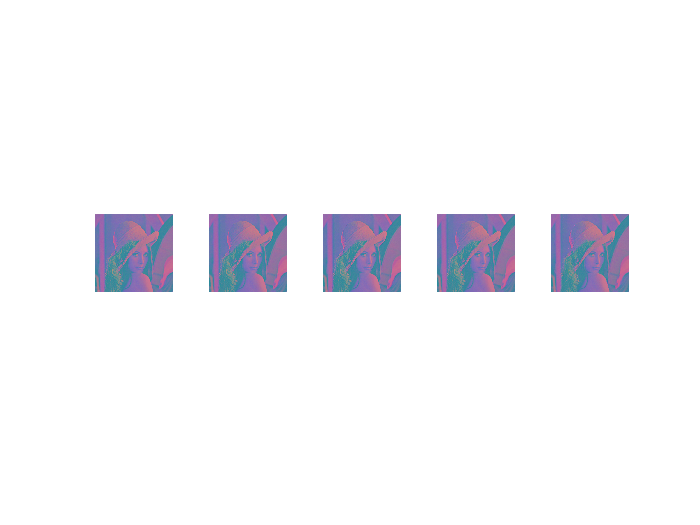

I1=cat(3,y,cbSubsampledFourTwoTwo,crSubsampledFourTwoTwo);

I2=cat(3,y,cbSubsampledFourOneOne,crSubsampledFourOneOne);

I3=cat(3,y,cbSubsampledFourTwoZero,crSubsampledFourTwoZero);

I4=cat(3,ySubsampledFourOneOne,cb,cr);

figure();
subplot(1,5,1); imshow(Iycbcr)
subplot(1,5,2); imshow(I1)
subplot(1,5,3); imshow(I2)
subplot(1,5,4); imshow(I3)
subplot(1,5,5); imshow(I4)

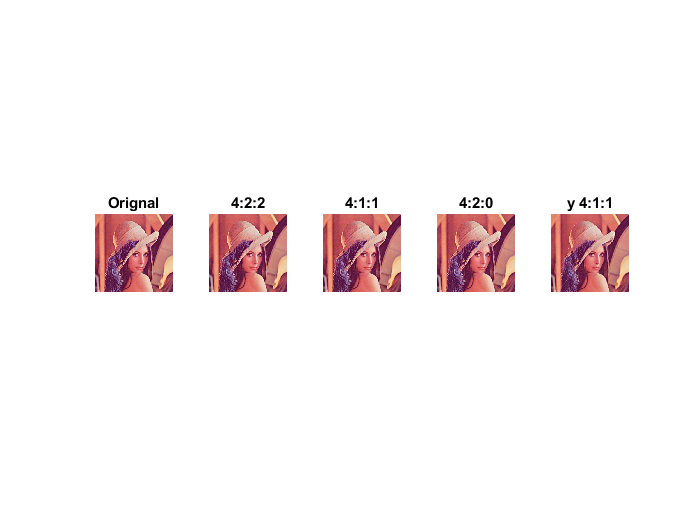


I1=ycbcr2rgb(I1);
I2=ycbcr2rgb(I2);
I3=ycbcr2rgb(I3);
I4=ycbcr2rgb(I4);

figure();
subplot(1,5,1); imshow(I),title('Orignal')
subplot(1,5,2); imshow(I1),title('4:2:2')
subplot(1,5,3); imshow(I2),title('4:1:1')
subplot(1,5,4); imshow(I3),title('4:2:0')
subplot(1,5,5); imshow(I4),title('y 4:1:1')


immse(I,I1)

ans = 13.6720

immse(I,I2)

ans = 31.7164

immse(I,I3)

ans = 18.7326

immse(I,I4)

ans = 186.6265